# Live script to test the two compartment model

% adding the model to the matlab path
addpath(genpath('D:\Projekte\two_comp_pump'))


## generating stimulus


dt = 0.01; % [ms] time steps

% original stimulus used in Meiser 2019 in 0.01 ms bins
load('D:\Projekte\two_comp_pump\data\originalstimulus_binsize_0p01ms.mat')
Iinj = stim_Tcharacteristics .* 1000; % [pA]


## pump parameters

% assigning pump parameters to a 1x3 array to test different parameter
% values

P(1) = 0;          % [uA] max pump current (=800[pA])
P(2) = 10 * 0.06e-6;    % conversion factor from INa into [Na] [mM/pA.ms]
P(3) = 2 * 0.06e-6;     % conversion factor from Ipump into [Na] [mM/pA.ms]

## call model

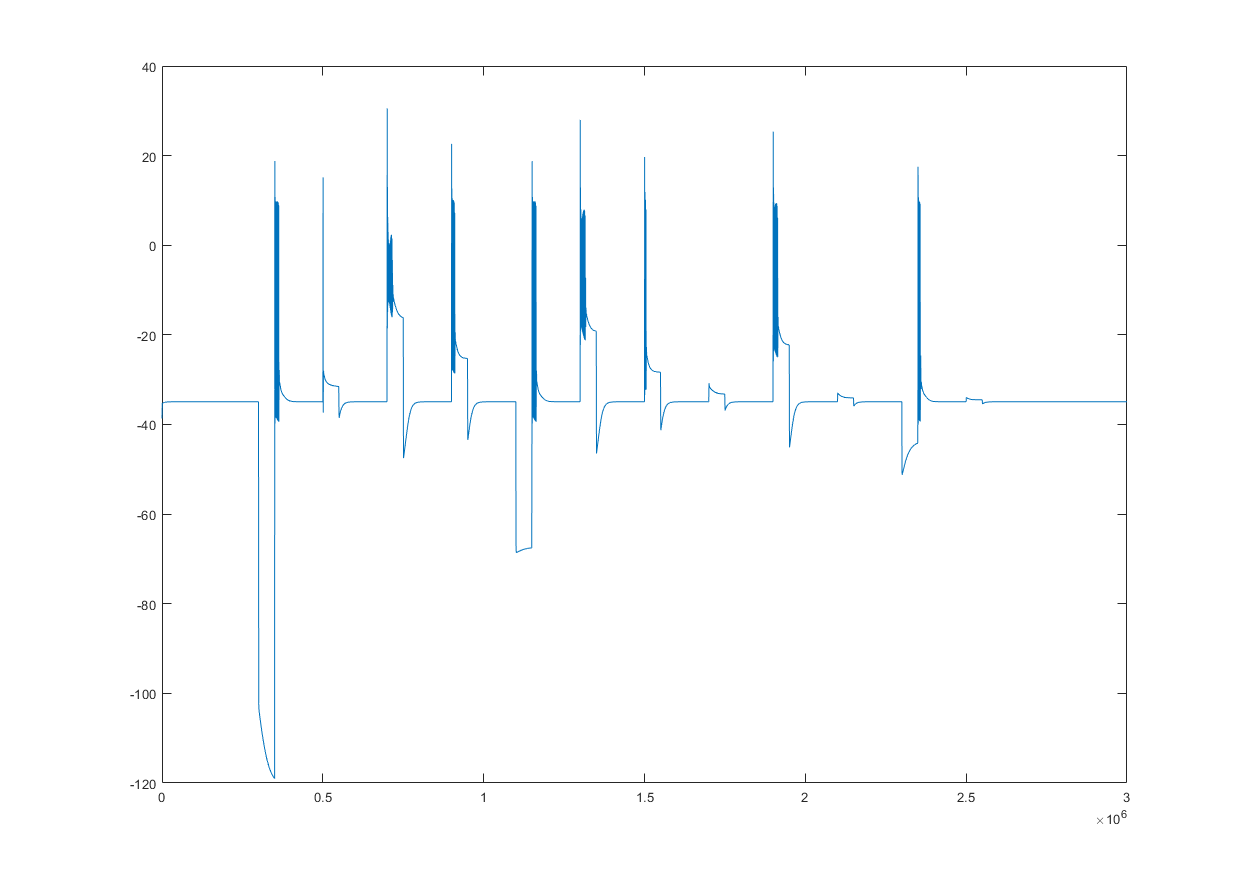

[V1, V2] = TcellDoublePumpFitting(Iinj, dt, P, 0);

plot(V1)

## analyse response

subthrFeat = subthranalysis(V1);
spikeFeatureVals = spikeanalysis(V1);